# Judd wavelength estimates from Maxwell's paper

The Judd wavelength are derived by scaling the Maxwell values by a factor of 3.6942. 

As we explain below, we think this perfect linear relationship is off by about 10 nm. In plotting the figures we use

The small additive term could easily arise given the nature of Maxwell's instrument.

Here is Judd's reasoning about Maxwell's wavelengths.

    "The wavelengths are expressed in millionths of a Paris inch." On the assumption that a Paris inch is 25·4 mm, this implies that a certain red  part of the spectrum has a wavelength of 0·002425 ><. 25·4 0·06160 mm 6  1,600 nm . An inquiry directed to the National Bureau of Standard ~ Office  of Weights and Measures disclosed that one Paris inch is not 25·4 but 27·07 mm, and this value would place this red part of the spectrum at  65,545 nm. It seems likely that when Maxwell stated that the wavelengths are expressed in millionths of a Paris inch, he meant tha the unit was  one Paris inch 10^8· This assumption has been used to find the wavelengths listed in Table I in nm. It will be noted that by this assumption, the colour names given to the various parts of the spectrum by Maxwell accord well with the names currently given to them. (p. 349)"

## Initialize

clear; close all;

We adjust by a small amount (10 nm) because the fits are improved.  We find it easy to imagine that Maxwell had a difficult time getting the offset of his instrument calibrated to within 10 nm. 

## Maxwell's determination of the wavelengths from the indices

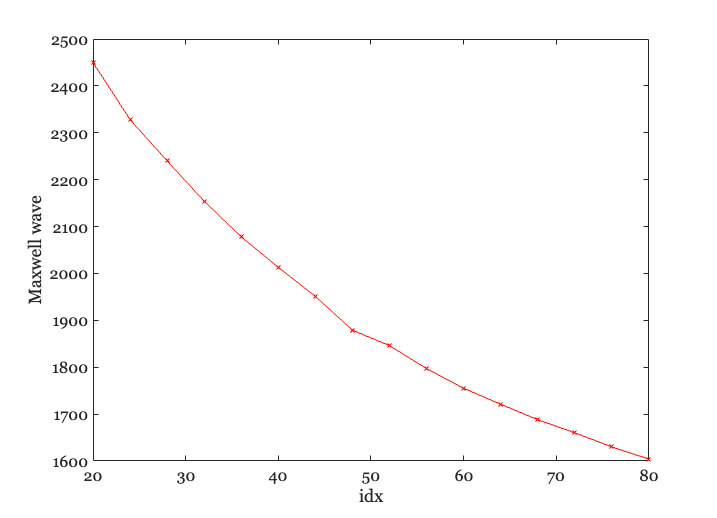

% Table II
maxwellWave = [
    20 2450
    24 2328
    28 2240
    32 2154
    36 2078
    40 2013
    44 1951
    48 1879
    52 1846
    56 1797
    60 1755
    64 1721
    68 1688
    72 1660
    76 1630
    80 1604];

ieNewGraphWin;
plot(maxwellWave(:,1),maxwellWave(:,2),'-x');
xlabel('idx'); ylabel('Maxwell wave');

## Judd says, however,

Judd says that the three primaries (24, 44, 68) are the wavelengths 456.9, 528.1 and 630.2. Notice that a longer index is a shorter wavelength according to Maxwell.  I arranged the idx and primaries in the same order. The Judd 1961 paper asserts that Maxwell's indices correspond to these wavelengths.  He also provides the primaries. These are cited in Qasim's paper, too.

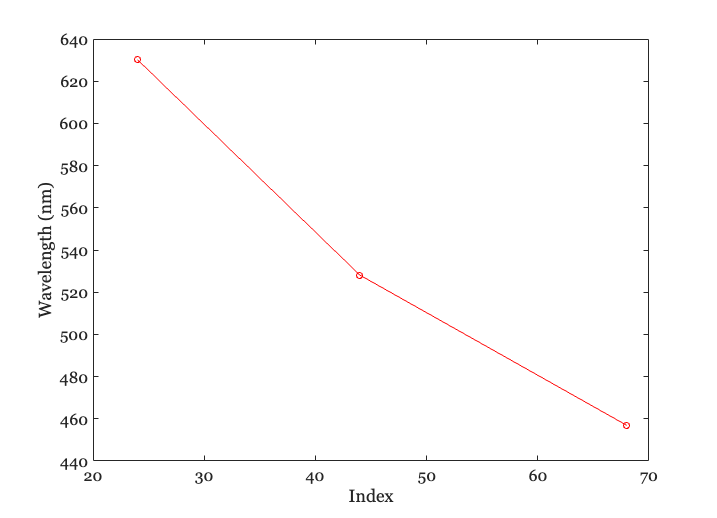

ieNewGraphWin;
idx = [24 44 68];
primaries = [630.2 528.1 456.9];
plot(idx,primaries,'-o');
xlabel('Index'); ylabel('Wavelength (nm)');

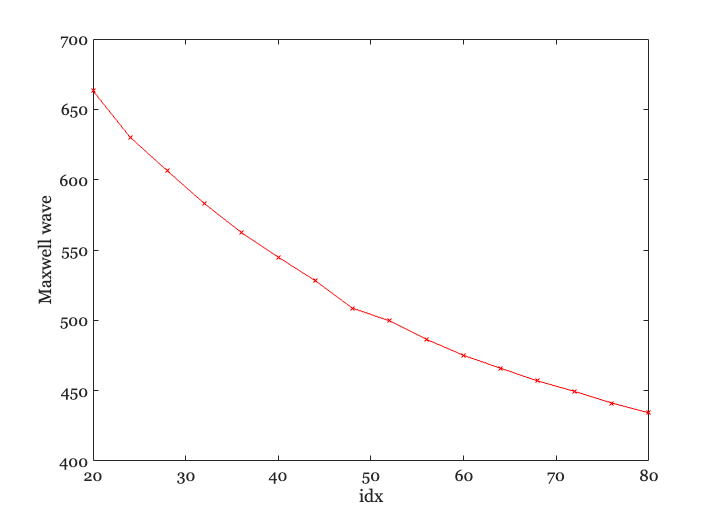


% This is from Judd's Table I
juddWave = [
    20 663.2
    24 630.2
    28 606.4
    32 583.1
    36 562.5
    40 544.9
    44 528.1
    48 508.6
    52 499.7
    56 486.4
    60 475.1
    64 465.9
    68 456.9
    72 449.4
    76 441.2
    80 434.2];

ieNewGraphWin;
plot(juddWave(:,1),juddWave(:,2),'-x');
xlabel('idx'); ylabel('Maxwell wave');

## What is the relationship?

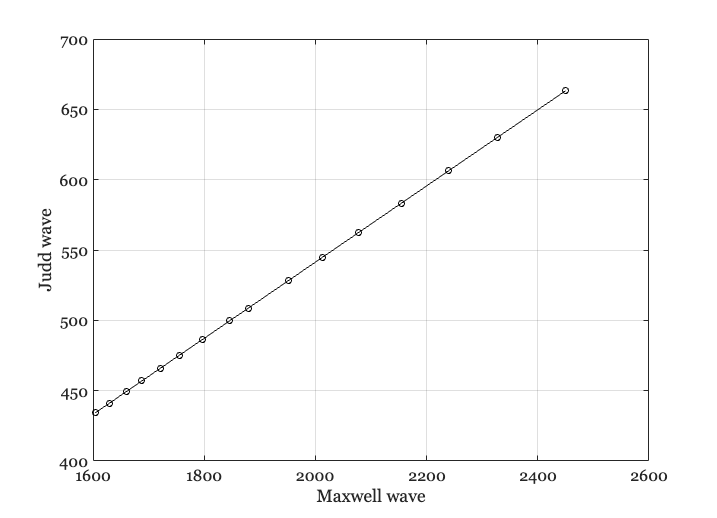

ieNewGraphWin;
plot(maxwellWave(:,2),juddWave(:,2),'k-o');
grid on;
xlabel('Maxwell wave'); ylabel('Judd wave');

## Fit a line and show that the slope is pretty much the whole deal.

[slope, offset] = ieFitLine(maxwellWave(:,2),juddWave(:,2));
ratios = maxwellWave(:,2)./juddWave(:,2);

ieNewGraphWin;
plot(juddWave(:,2),maxwellWave(:,2)/mean(ratios),'-o');
mean(ratios)

ans = 3.6942

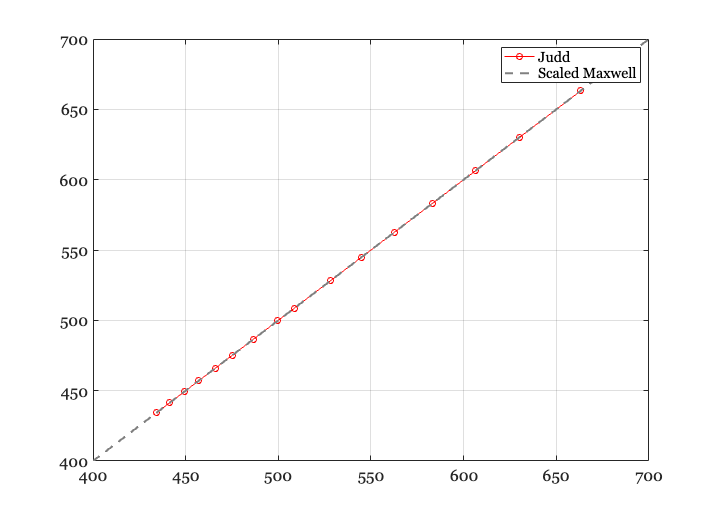

identityLine;
legend('Judd','Scaled Maxwell');